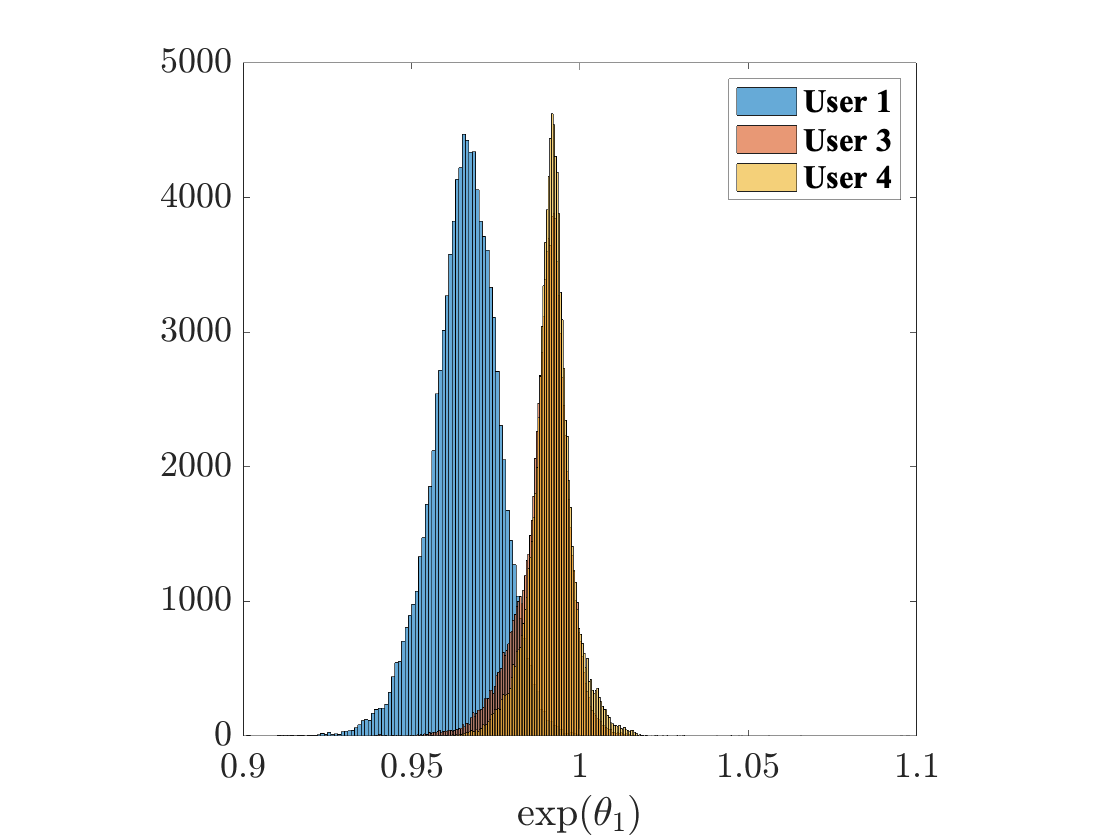

clc
clear
close all
%% ========================================================================
%% ========================================================================
%% ========================================================================
% Assignment 7, Bayesian statistics, LTU, January 2020, 
% Author: Hassan Bahaloo, PhD student, division of experimental mechanics,
%% ========================================================================
%% ========================================================================
%% ========================================================================
% inputs
% reaction time in mili seconds
y = [607, 583, 521, 494, 369, 782, 570, 678, 467, 620, 425, 395, 346, 361, ...
    310, 300, 382, 294, 315, 323, 421, 339, 398, 328, 335, 291, 329, 310, ...
    294, 321, 286, 349, 279, 268, 293, 310, 259, 241, 243, 272, 247, 275,...
    220, 245, 268, 357, 273, 301, 322, 276, 401, 368, 149, 507, 411, 362,...
    358, 355, 362, 324, 332, 268, 259, 274, 248, 254, 242, 286, 276, 237,...
    259, 251, 239, 247, 260, 237, 206, 242, 361, 267, 245, 331, 357, 284,...
    263, 244, 317, 225, 254, 253, 251, 314, 239, 248, 250, 200, 256, 233,...
    427, 391, 331, 395, 337, 392, 352, 381, 330, 368, 381, 316, 335, 316,...
    302, 375, 361, 330, 351, 186, 221, 278, 244, 218, 126, 269, 238, 194,...
    384, 154, 555, 387, 317, 365, 357, 390, 320, 316, 297, 354, 266, 279,...
    327, 285, 258, 267, 226, 237, 264, 510, 490, 458, 425, 522, 927, 555,...
    550, 516, 548, 560, 545, 633, 496, 498, 223, 222, 309, 244, 207, 258,...
    255, 281, 258, 226, 257, 263, 266, 238, 249, 340, 247, 216, 241, 239,...
    226, 273, 235, 251, 290, 473, 416, 451, 475, 406, 349, 401, 334, 446,...
    401, 252, 266, 210, 228, 250, 265, 236, 289, 244, 327, 274, 223, 327,...
    307, 338, 345, 381, 369, 445, 296, 303, 326, 321, 309, 307, 319, 288,...
    299, 284, 278, 310, 282, 275, 372, 295, 306, 303, 285, 316, 294, 284,...
    324, 264, 278, 369, 254, 306, 237, 439, 287, 285, 261, 299, 311, 265,...
    292, 282, 271, 268, 270, 259, 269, 249, 261, 425, 291, 291, 441, 222,...
    347, 244, 232, 272, 264, 190, 219, 317, 232, 256, 185, 210, 213, 202,...
    226, 250, 238, 252, 233, 221, 220, 287, 267, 264, 273, 304, 294, 236,...
    200, 219, 276, 287, 365, 438, 420, 396, 359, 405, 397, 383, 360, 387,...
    429, 358, 459, 371, 368, 452, 358, 371];

% user indices
ind = [1, 1, 1, 1, 1, 2, 2, 2, 2, 2, 3, 3, 3, 3, 3, 3, 3, 3, 3, 4, 5, 5,...
    5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 6, 6, 6, 6, 6, 6, 6, 6, 6,...
    7, 7, 7, 7, 7, 8, 8, 8, 8, 8, 9, 9, 9, 9, 9, 10, 10, 10, 10, 10, 10,...
    10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 11, 11, 11, 11, 11,...
    11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 12, 12,...
    12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12,...
    12, 13, 13, 13, 13, 13, 13, 13, 13, 13, 13, 14, 14, 14, 14, 14, 14,...
    14, 14, 14, 14, 14, 14, 14, 15, 15, 15, 15, 15, 15, 16, 16, 16, 16,...
    16, 17, 17, 17, 17, 17, 18, 18, 18, 18, 18, 19, 19, 19, 19, 19, 20,...
    20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20,...
    20, 20, 21, 21, 21, 21, 21, 21, 21, 21, 21, 21, 22, 22, 22, 22, 22,...
    22, 22, 22, 22, 22, 22, 22, 23, 23, 23, 23, 23, 23, 23, 23, 23, 23,...
    24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24,...
    24, 24, 24, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 26,...
    26, 26, 26, 26, 27, 27, 27, 27, 27, 28, 28, 28, 28, 28, 28, 28, 28,...
    28, 29, 29, 29, 29, 29, 29, 29, 29, 29, 29, 30, 30, 30, 30, 30, 30,...
    31, 31, 31, 31, 31, 32, 32, 32, 32, 32, 33, 34, 34, 34, 34, 34, 34,...
    34, 34, 34, 34, 34, 34, 34, 34, 34, 34, 34, 34];

child = [1, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 0, 0, ...
    0, 0, 1, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0];

% attempts:
x = [1, 2, 3, 4, 5, 1, 2, 3, 4, 5, 1, 2, 3, 4, 5, 6, 7, 8, 9, 1, 1, 2, 3,...
    4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 1, 2, 3, 4, 5, 6, 7, 8, 9, 1, 2, 3,...
    4, 5, 1, 2, 3, 4, 5, 1, 2, 3, 4, 5, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14,...
    15, 16, 17, 18, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19,...
    20, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 1, 2,...
    3, 4, 5, 6, 7, 8, 9, 10, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 1, 2, 3, 4,...
    5, 6, 1, 2, 3, 4, 5, 1, 2, 3, 4, 5, 1, 2, 3, 4, 5, 1, 2, 3, 4, 5, 1, 2, 3, 4, 5,...
    6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 1, 2, 3, 4, 5, 6, 7, 8,...
    9, 10, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 1,...
    2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 1, 2, 3, 4,...
    5, 6, 7, 8, 9, 10, 11, 12, 13, 1, 2, 3, 4, 5, 1, 2, 3, 4, 5, 1, 2, 3, 4, 5, 6, 7,...
    8, 9, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 1, 2, 3, 4, 5, 6, 1, 2, 3, 4, 5, 1, 2, 3, 4,...
    5, 1, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18];
%% ========================================================================
% normalizing x data
zx = (x - mean(x))/std(x);

% Getting each theta_j set in logrithmic form
l = 0;
for i =1:max(ind)
    logy{i} = log(y(1+l:l+length(ind(ind==i))));
    l = l+length(ind(ind==i));
end

for i=1:max(ind)
    theta(i) = (mean(logy{i}));
end

%Standardization of data
zlogy = (log(y)-mean(log(y)))/std(log(y));

%slice sampling
beta0 = rand(2*max(ind)+7,1);
nsamples = 100000;

%% slice sampler for assignment 6
SL_SAMPLE = slicesample(beta0,nsamples,'logpdf',@(beta) ...
    log_post(beta, zlogy, zx, ind, child));

%% getting desired parameters from slice sampler
eta_0 = SL_SAMPLE(:,1:max(ind));
eta_1 = SL_SAMPLE(:,max(ind)+1:2*max(ind));

b00= SL_SAMPLE(:,end-6);
b01 = SL_SAMPLE(:,end-5);
tau_0 = SL_SAMPLE(:,end-4);

b10 = SL_SAMPLE(:,end-3);
b11 = SL_SAMPLE(:,end-2);
tau_1 = SL_SAMPLE(:,end-1);

sigma = SL_SAMPLE(:,end);

mu_0 = b00 + b01*child;
mu_1 = b10 + b11*child;

theta_0 = mu_0 + eta_0.*tau_0;
theta_1 = mu_1 + eta_1.*tau_1;

% un-normalizing theta_0, theta_1 and sigma for plotting purposes
theta_0_unnorm = std(log(y)).*(theta_0 - theta_1*mean(x)./std(x)) + mean(log(y));
theta_1_unnorm = theta_1.*std(log(y))./std(x);
sigma_unnorm = sigma.*std(log(y));
%% ========================================================================
% plotting the results
figure(1)
histogram(exp(theta_1_unnorm(:,1)))
hold on
histogram(exp(theta_1_unnorm(:,3)))
hold on
histogram(exp(theta_1_unnorm(:,4)))
legend({'User 1','User 3','User 4'})
axis('square');
xlim([0.9 1.1])
set(gca,'TickLabelInterpreter','latex')
xlabel('$\exp(\theta_1)$','FontAngle','italic','Interpreter','latex');
% ytickformat('0.1')
set(gca,'DefaultTextFontSize',18)
set(gca, 'FontName', 'Times New Roman')
title('','Interpreter','latex');
set(gca,'FontSize',18)
set(gca,'fontweight','bold')
set(gca, 'FontName', 'Times New Roman')

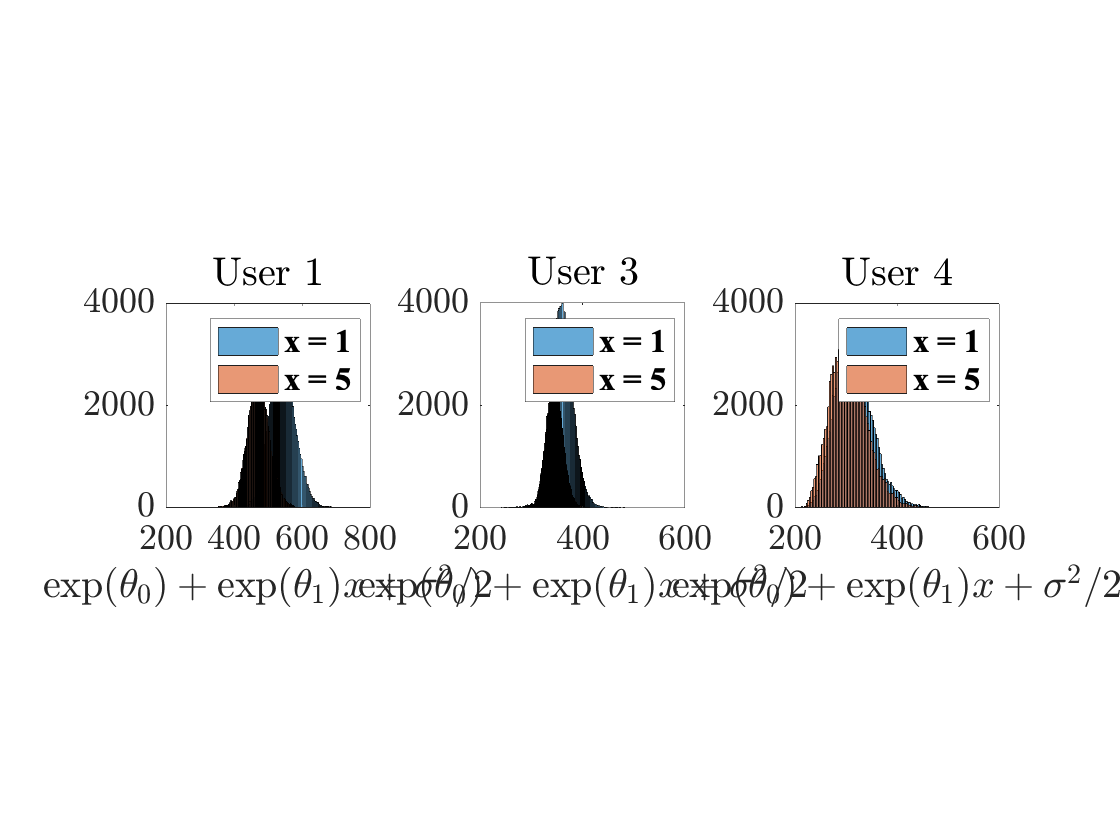


% task 3
figure(2)
subplot(1,3,1)
histogram(exp(theta_0_unnorm(:,1)+theta_1_unnorm(:,1)*(1)+sigma_unnorm.^2/2))
hold on
histogram(exp(theta_0_unnorm(:,1)+theta_1_unnorm(:,1)*(5)+sigma_unnorm.^2/2))
legend({'x = 1','x = 5'})
axis('square');
xlim([200 800])
set(gca,'TickLabelInterpreter','latex')
xlabel('$\exp(\theta_0)+\exp(\theta_1)x+\sigma^2/2$','FontAngle','italic','Interpreter','latex');
% ytickformat('0.1')
set(gca,'DefaultTextFontSize',18)
set(gca, 'FontName', 'Times New Roman')
title('User 1','Interpreter','latex');
set(gca,'FontSize',18)
set(gca,'fontweight','bold')
set(gca, 'FontName', 'Times New Roman')

subplot(1,3,2)
histogram(exp(theta_0_unnorm(:,3)+theta_1_unnorm(:,3)*(1)+sigma_unnorm.^2/2))
hold on
histogram(exp(theta_0_unnorm(:,3)+theta_1_unnorm(:,3)*(5)+sigma_unnorm.^2/2))
legend({'x = 1','x = 5'})
axis('square');
xlim([200 600])
set(gca,'TickLabelInterpreter','latex')
xlabel('$\exp(\theta_0)+\exp(\theta_1)x+\sigma^2/2$','FontAngle','italic','Interpreter','latex');
% ytickformat('0.1')
set(gca,'DefaultTextFontSize',18)
set(gca, 'FontName', 'Times New Roman')
title('User 3','Interpreter','latex');
set(gca,'FontSize',18)
set(gca,'fontweight','bold')
set(gca, 'FontName', 'Times New Roman')

subplot(1,3,3)
histogram(exp(theta_0_unnorm(:,4)+theta_1_unnorm(:,4)*(1)+sigma_unnorm.^2/2))
hold on
histogram(exp(theta_0_unnorm(:,4)+theta_1_unnorm(:,4)*(5)+sigma_unnorm.^2/2))
legend({'x = 1','x = 5'})
axis('square');
xlim([200 600])
set(gca,'TickLabelInterpreter','latex')
xlabel('$\exp(\theta_0)+\exp(\theta_1)x+\sigma^2/2$','FontAngle','italic','Interpreter','latex');
% ytickformat('0.1')
set(gca,'DefaultTextFontSize',18)
set(gca, 'FontName', 'Times New Roman')
title('User 4','Interpreter','latex');
set(gca,'FontSize',18)
set(gca,'fontweight','bold')
set(gca, 'FontName', 'Times New Roman')

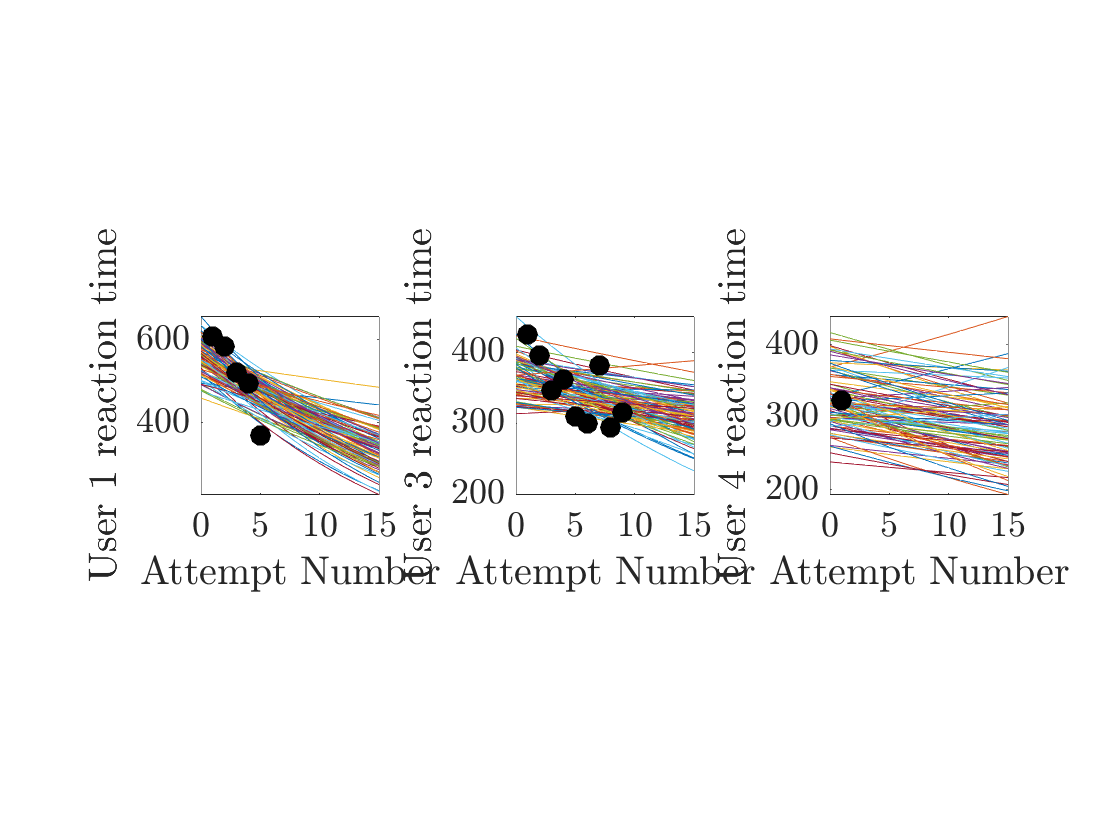

% plotting credible regression lines
figure(3)
attempt = 0:1:15;
SI = 0.5*nsamples:0.005*nsamples:nsamples;
YL1 = (exp(theta_0_unnorm(SI ,1)+theta_1_unnorm(SI ,1).*attempt+sigma_unnorm(SI ).^2/2));
subplot(1,3,1)
plot(attempt,YL1)
hold on
plot([1:5],[607, 583, 521, 494, 369],'o', 'MarkerSize',10,...
    'MarkerEdgeColor','black',...
    'MarkerFaceColor',[0 .0 .0])
axis('square');
set(gca,'TickLabelInterpreter','latex')
xlabel('Attempt Number','FontAngle','italic','Interpreter','latex');
% ytickformat('0.1')
set(gca,'DefaultTextFontSize',18)
set(gca, 'FontName', 'Times New Roman')
ylabel('User 1 reaction time','Interpreter','latex');
set(gca,'FontSize',18)
set(gca,'fontweight','bold')
set(gca, 'FontName', 'Times New Roman')
YL3 = (exp(theta_0_unnorm(SI ,3)+theta_1_unnorm(SI ,3).*attempt+sigma_unnorm(SI ).^2/2));
subplot(1,3,2)
plot(attempt,YL3)
hold on
plot([1:9],[425, 395, 346, 361, 310, 300, 382, 294, 315],'o', 'MarkerSize',10,...
    'MarkerEdgeColor','black',...
    'MarkerFaceColor',[0 .0 .0])
axis('square');
set(gca,'TickLabelInterpreter','latex')
xlabel('Attempt Number','FontAngle','italic','Interpreter','latex');
% ytickformat('0.1')
set(gca,'DefaultTextFontSize',18)
set(gca, 'FontName', 'Times New Roman')
ylabel('User 3 reaction time','Interpreter','latex');
set(gca,'FontSize',18)
set(gca,'fontweight','bold')
set(gca, 'FontName', 'Times New Roman')

YL4 = (exp(theta_0_unnorm(SI ,4)+theta_1_unnorm(SI ,4).*attempt+sigma_unnorm(SI ).^2/2));
subplot(1,3,3)
plot(attempt,YL4)
hold on
plot(1,323,'o', 'MarkerSize',10,...
    'MarkerEdgeColor','black',...
    'MarkerFaceColor',[0 .0 .0])
axis('square');
set(gca,'TickLabelInterpreter','latex')
xlabel('Attempt Number','FontAngle','italic','Interpreter','latex');
% ytickformat('0.1')
set(gca,'DefaultTextFontSize',18)
set(gca, 'FontName', 'Times New Roman')
ylabel('User 4 reaction time','Interpreter','latex');
set(gca,'FontSize',18)
set(gca,'fontweight','bold')
set(gca, 'FontName', 'Times New Roman')

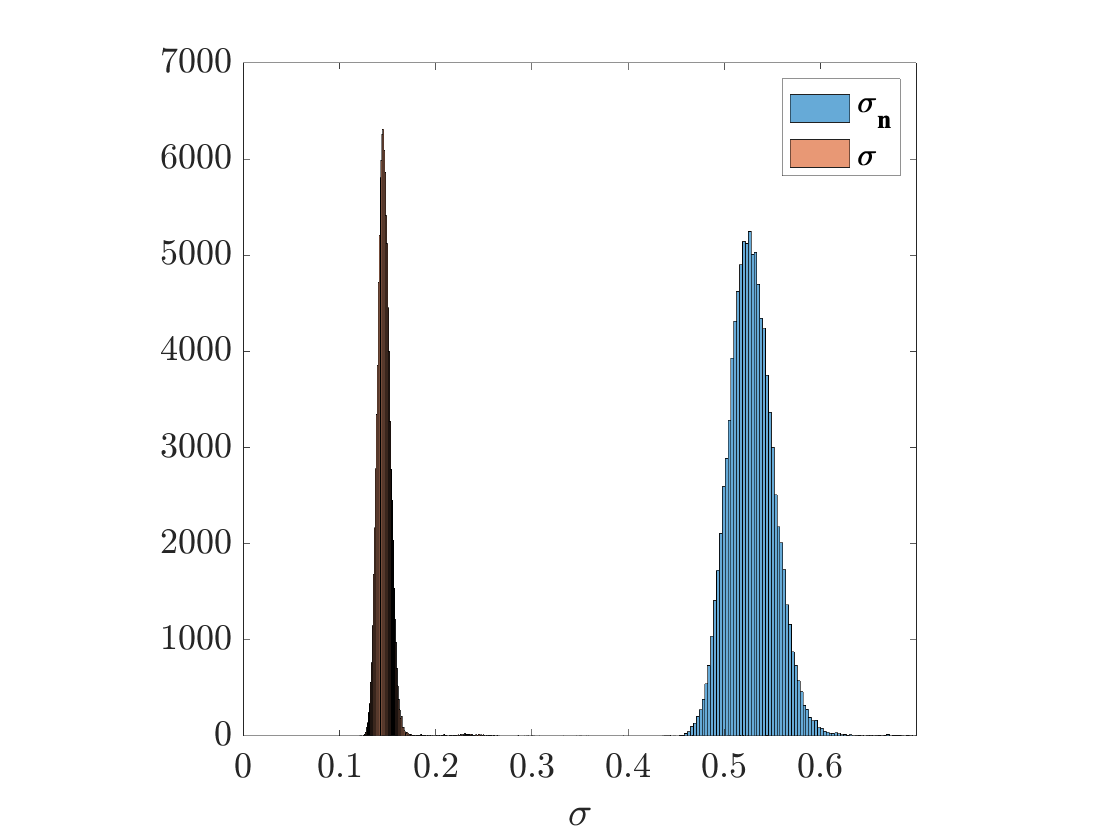


% plotting sigma
figure(4)
histogram(sigma)
hold on
histogram(sigma.*std(log(y)))
xlim([0 .7])
axis('square');
set(gca,'TickLabelInterpreter','latex')
xlabel('$\sigma$','FontAngle','italic','Interpreter','latex');
% ytickformat('0.1')
set(gca,'DefaultTextFontSize',18)
set(gca, 'FontName', 'Times New Roman')
ylabel('','Interpreter','latex');
set(gca,'FontSize',18)
set(gca,'fontweight','bold')
set(gca, 'FontName', 'Times New Roman')
legend({'\sigma_n','\sigma'})

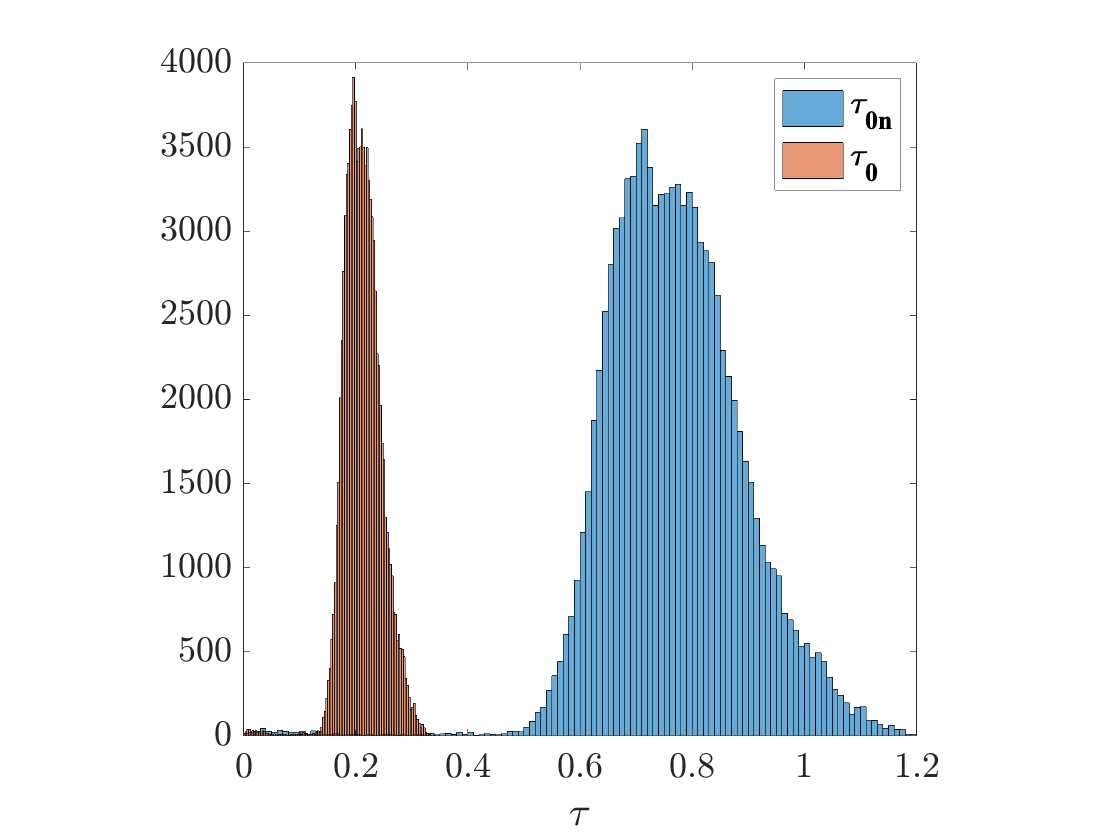


% plotting tau
figure(5)
histogram(tau_0)
hold on
histogram(tau_0.*std(log(y)))
xlim([0 1.2])
axis('square');
set(gca,'TickLabelInterpreter','latex')
xlabel('$\tau$','FontAngle','italic','Interpreter','latex');
% ytickformat('0.1')
set(gca,'DefaultTextFontSize',18)
set(gca, 'FontName', 'Times New Roman')
ylabel('','Interpreter','latex');
set(gca,'FontSize',18)
set(gca,'fontweight','bold')
set(gca, 'FontName', 'Times New Roman')
legend({'\tau_0_n','\tau_0'})

% credible regression lines

%% ========================================================================
% posterior distribution

function lpost=log_post(beta, zlogy, zx, ind, child)

J = max(ind);

eta_0 = beta(1:J);
eta_1 = beta(J+1:2*J);

tau_0 = beta(end-4);  
tau_1 = beta(end-1);

sigma = beta(end);

if (sigma > 0) && (tau_0 > 0) && (tau_1 > 0)
    lpost = log_liklihood(beta,zlogy, zx, ind, child) + ...
        log_prior_theta(eta_0,zeros(1,J),1.0) + ...
        log_prior_theta(eta_1,zeros(1,J),1.0) +  ...
        log_prior_sigma(beta) + ...
        log_prior_tau_0(beta) + ...
        log_prior_tau_1(beta);
else
    lpost = -inf;
end
end
%% ========================================================================
% Priors
function lpsigma = log_prior_sigma(beta)
sigma = beta(end);
if sigma >0;lpsigma = 0;else;lpsigma = -inf;end
end

function lptau_0 =log_prior_tau_0(beta)
tau_0 = beta(end-4);
if tau_0 >0;lptau_0 = 0;else;lptau_0 = -inf;end
end

function lptau_1 =log_prior_tau_1(beta)
tau_1 = beta(end-1);
if tau_1 >0;lptau_1= 0;else;lptau_1 = -inf;end
end

function log_prior_theta = log_prior_theta(theta,mu,sigma)
log_prior_theta = sum(-log(sigma) - 0.5 * ((theta - mu) / sigma).^2);
end
%% ========================================================================
% liklehood distribution
function ll = log_liklihood(beta,zlogy, zx, ind, child)

J = max(ind);

eta_0 = beta(1:J);
eta_1 = beta(J+1:2*J);

b00 = beta(end-6);
b01 = beta(end-5);
tau_0 = beta(end-4);

mu_0 = b00 + b01*child;

b10 = beta(end-3);
b11 = beta(end-2);  
tau_1 = beta(end-1);

mu_1 = b10 + b11*child;

sigma = beta(end);

theta_0 = mu_0  +  eta_0*tau_0;
theta_1 = mu_1  +  eta_1*tau_1;

ll = 0;
for i = 1: length(zlogy) 
    j = ind(i);
    MU = theta_0(j) + theta_1(j) * zx(i);   %  mean (regressioned)
    ll = ll -log(sigma) - 0.5 * ((zlogy(i) - MU) / sigma)^2;
end
end
